## Gabriel Werpel Fernandes

## May 2024

## Load Data

% Close all figures and clear variables
clc;
close all;
clearvars;

%Process EEG Data
data = processAllEEGData();

Data for file A1_Full_Block.bdf processed successfully
Data for file A3_Full_Block.bdf processed successfully
Data for file A4_Full_Block.bdf processed successfully
Data for file A6_Alpha.bdf processed successfully
Data for file A7_Alpha.bdf processed successfully
Data for file A8_Alpha.bdf processed successfully
Data for file A9_Alpha.bdf processed successfully
Data for file C11_Alpha.bdf processed successfully
Data for file C12_Alpha.bdf processed successfully
Data for file C13_Alpha.bdf processed successfully
Data for file C14_Alpha.bdf processed successfully
Data for file C15_Alpha.bdf processed successfully
Data for file C1_Alpha.bdf processed successfully


## Plot Time-Series

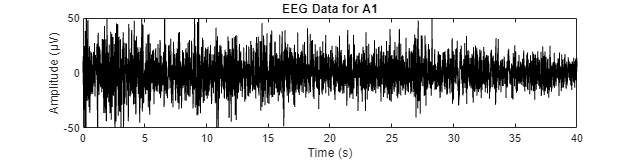

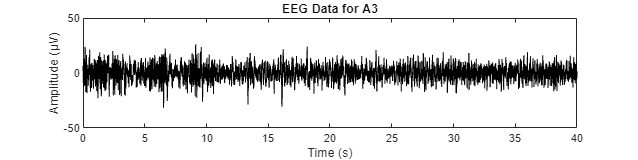

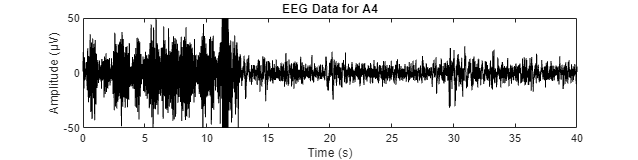

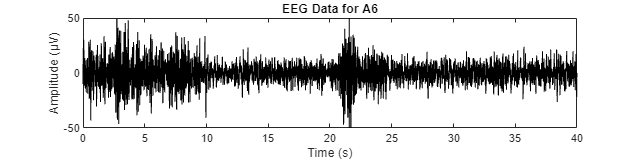

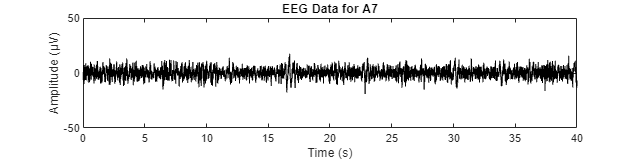

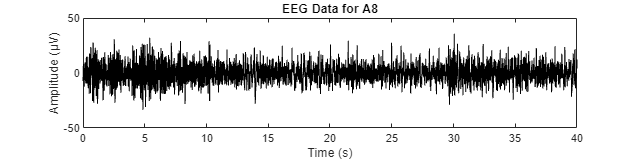

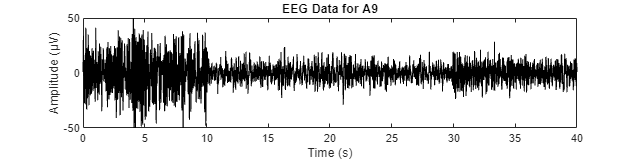

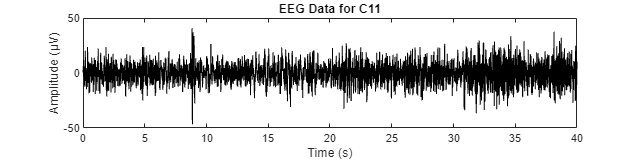

% Plot all EEG data
plotAllEEGData(data);

## Segment Data

% Segment the EEG data
segmentedData = segmentEEGDataNew(data);

## Time-Domain Analysis

### Statistical Measures: Mean, Variance, Std. Deviation, Skewness and Kurtosis

% Calculate and display the extended statistics for all keys and sections
extendedStatisticsResults = calculateExtendedStatisticsForAllSections(segmentedData);

      Key             Section             DataType      Mean      Variance    StandardDeviation    Skewness    Kurtosis
    _______    ______________________    __________    _______    ________    _________________    ________    ________

    {'A1' }    {'EC'                }    {'Normal'}     -0.158     320.02          17.889            0.012       3.441 
    {'A1' }    {'EO'                }    {'Normal'}      0.051        150          12.247           -0.039       3.837 
    {'A1' }    {'DEC'               }    {'Normal'}      -0.04      108.7          10.426            0.292       3.873 
    {'A1' }    {'NDEC'              }    {'Normal'}      0.042     78.528           8.862            0.031        3.09 
    {'A

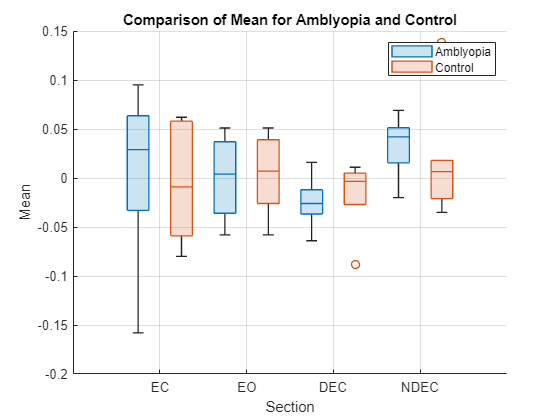

% Load the data
data = readtable('TableA.1.1.csv');

% Call the function for each metric
plotBoxChart(data, 'Mean', 'Mean');

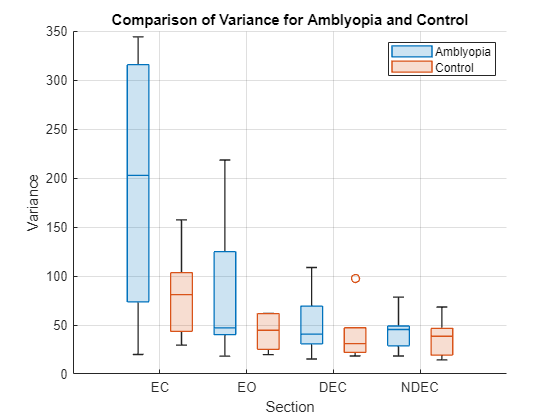

plotBoxChart(data, 'Variance', 'Variance');

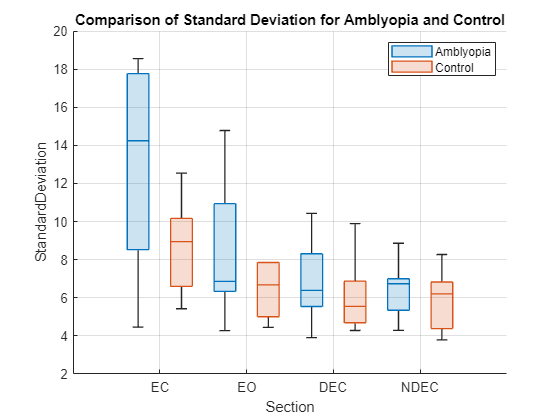

plotBoxChart(data, 'StandardDeviation', 'Standard Deviation');

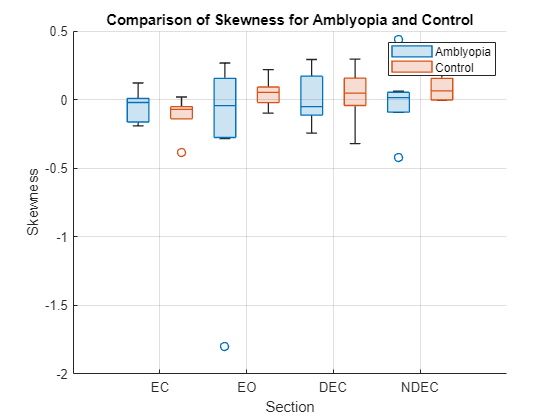

plotBoxChart(data, 'Skewness', 'Skewness');

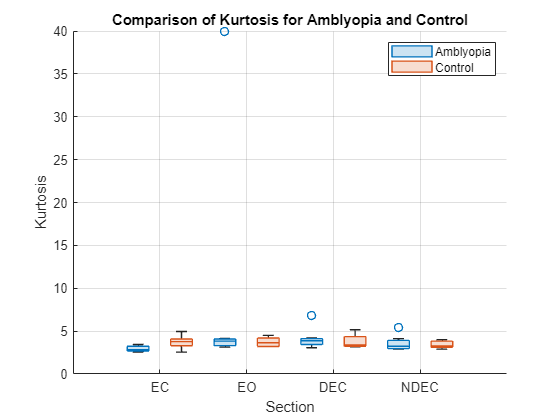

plotBoxChart(data, 'Kurtosis', 'Kurtosis');

ans = struct with fields:
     A1: [1×1 struct]
     A3: [1×1 struct]
     A4: [1×1 struct]
     A6: [1×1 struct]
     A7: [1×1 struct]
     A8: [1×1 struct]
     A9: [1×1 struct]
    C11: [1×1 struct]
    C12: [1×1 struct]
    C13: [1×1 struct]
    C14: [1×1 struct]
    C15: [1×1 struct]
     C1: [1×1 struct]


### Statistical comparison between groups.

           Section             DataType        Metric         A_Mean      A_StdDev      C_Mean      C_StdDev    P_Value     H
    ______________________    __________    ____________    __________    ________    __________    ________    ________    _

    {'Difference_NDEC_EO'}    {'normal'}    {'std'     }       -1.8383      3.6944      -0.52517      1.4669           0    1
    {'NDEC'              }    {'normal'}    {'mean'    }      0.032857    0.029701     -0.020833    0.036559    0.013986    1
    {'EC'                }    {'normal'}    {'kurtosis'}        2.9617     0.33352         3.743     0.80321    0.051282    0
    {'Difference_NDEC_EO'}    {'normal'}    {'mean'    }      0

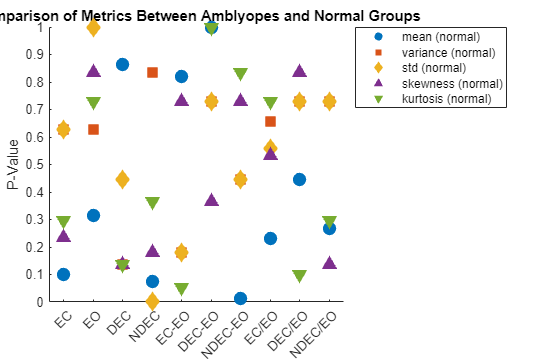

% Compare various metrics between A* and C* groups for all sections and data types
compareMetricsByGroupsAndDataTypes(extendedStatisticsResults);

### Peak Analysis


% Perform peak analysis with custom parameters
peakData = performPeakAnalysis(segmentedData, 'MinPeakProminence', [0.5, 1, 1.5], 'MinPeakDistance', [50, 100, 150], 'NPeaks', [5, 10, 15]);

      Time       Peak     Width     Prominence
    ________    ______    ______    __________

    0.015625    15.037    13.942      12.094  
    0.052734     33.79    65.582       32.46  
    0.083008     7.537    11.372      5.8972  
     0.10889    24.352    20.356      22.908  
     0.14404    59.076    66.478       57.35  

      Time       Peak     Width     Prominence
    ________    ______    ______    __________

    0.023926    21.758     42.06      19.992  
    0.063477    23.126    19.489      22.221  
     0.12354    23.639    39.926      22.853  
     0.17627    17.061    64.464      16.231  
     0.22217    15.525    17.254      8.4097  

      Time       Peak     

Summary of Statistical Findings:
       ParamCombo        Condition        Metric          p_Value      h_Value
    _________________    _________    _______________    __________    _______

    {'P0_5_D50_N15' }    {'DEC' }     {'Peak Height'}    6.1927e-05       1   
    {'P1_5_D50_N15' }    {'DEC' }     {'Peak Height'}    0.00028846       1   
    {'P1_D50_N15'   }    {'DEC' }     {'Peak Height'}    0.00031845       1   
    {'P1_5_D50_N15' }    {'NDEC'}     {'Peak Height'}    0.00034018       1   
    {'P1_D50_N15'   }    {'NDEC'}     {'Peak Height'}    0.00052659       1   
    {'P1_5_D150_N15'}    {'NDEC'}     {'Peak Height'}     0.0006519       1   
    {'P0_5_D50_N15' }    {'NDEC'}     {'Peak Height'}    0.00093017       1   
    {'P0_5_D100_N15'}    {'DEC' }     {'Peak Height'}     0.0012791       1   
    {'

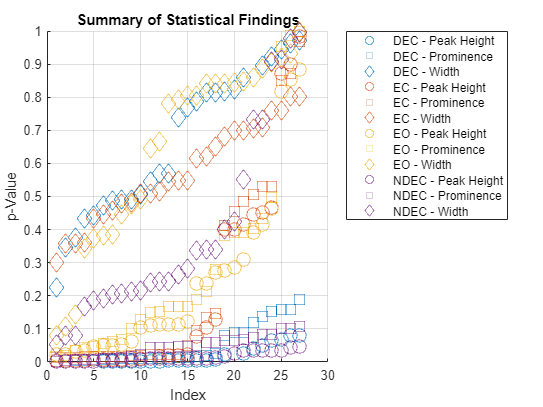

% Run the statistical analysis
analyzePeakData(peakData);

function peakData = performPeakAnalysis(segmentedData, varargin)
    % Parse input arguments
    p = inputParser;
    addParameter(p, 'MinPeakHeight', []);
    addParameter(p, 'Threshold', []);
    addParameter(p, 'MinPeakProminence', [0.5, 1, 1.5]);
    addParameter(p, 'MinPeakDistance', [50, 100, 150]);
    addParameter(p, 'NPeaks', [5, 10, 15]);
    addParameter(p, 'WidthReference', 'halfprom');
    addParameter(p, 'SortStr', 'none'); % Can be 'ascend', 'descend', or 'none'
    addParameter(p, 'Annotate', false);
    parse(p, varargin{:});

    % Get parsed input values
    minPeakHeight = p.Results.MinPeakHeight;
    threshold = p.Results.Threshold;
    minPeakProminenceValues = p.Results.MinPeakProminence;
    minPeakDistanceValues = p.Results.MinPeakDistance;
    nPeaksValues = p.Results.NPeaks;
    widthReference = p.Results.WidthReference;
    sortStr = p.Results.SortStr;
    annotate = p.Results.Annotate;

    % Initialize structure to store peak data
    peakData = struct;

    % Get all the keys for the groups (e.g., A1, A2, C1, etc.)
    groups = fieldnames(segmentedData);

    % Conditions to analyze
    conditions = {'EC', 'EO', 'DEC', 'NDEC'};

    % Iterate through each combination of parameter values
    for pIdx = 1:numel(minPeakProminenceValues)
        for dIdx = 1:numel(minPeakDistanceValues)
            for nIdx = 1:numel(nPeaksValues)
                minPeakProminence = minPeakProminenceValues(pIdx);
                minPeakDistance = minPeakDistanceValues(dIdx);
                nPeaks = nPeaksValues(nIdx);

                % Iterate through each group and condition
                for i = 1:numel(groups)
                    group = groups{i};
                    for j = 1:numel(conditions)
                        condition = conditions{j};

                        % Load the signal data
                        signal = segmentedData.(group).(condition); % Load the condition signal
                        signal = abs(signal); % Convert the signal to absolute values
                        Fs = segmentedData.(group).header.Fs; % Load the sampling frequency

                        % Generate the time vector
                        N = length(signal); % Number of samples
                        time = (0:N-1) / Fs; % Time vector

                        % Preprocessing: Optionally, you can smooth the data
                        smoothedSignal = smooth(signal, 5); % Using a moving average filter with window size 5

                        % Prepare name-value pairs for findpeaks
                        nvPairs = {};
                        if ~isempty(minPeakHeight)
                            nvPairs = [nvPairs, {'MinPeakHeight', minPeakHeight}];
                        end
                        if ~isempty(threshold)
                            nvPairs = [nvPairs, {'Threshold', threshold}];
                        end
                        nvPairs = [nvPairs, {'MinPeakProminence', minPeakProminence}];
                        nvPairs = [nvPairs, {'MinPeakDistance', minPeakDistance}];
                        nvPairs = [nvPairs, {'NPeaks', nPeaks}];
                        if ~strcmp(sortStr, 'none')
                            nvPairs = [nvPairs, {'SortStr', sortStr}];
                        end
                        nvPairs = [nvPairs, {'WidthReference', widthReference}];

                        % Peak Detection
                        [peaks, locs, width, prominence] = findpeaks(smoothedSignal, nvPairs{:});

                        % Save peak characteristics
                        paramCombo = sprintf('P%g_D%d_N%d', minPeakProminence, minPeakDistance, nPeaks);
                        paramCombo = strrep(paramCombo, '.', '_'); % Replace dot with underscore
                        if ~isfield(peakData, paramCombo)
                            peakData.(paramCombo) = struct;
                        end
                        if ~isfield(peakData.(paramCombo), group)
                            peakData.(paramCombo).(group) = struct;
                        end
                        peakData.(paramCombo).(group).(condition) = table(time(locs)', peaks, width, prominence, ...
                            'VariableNames', {'Time', 'Peak', 'Width', 'Prominence'});

                        % Visualization
                        if annotate
                            figure;
                            plot(time, signal, 'b'); hold on;
                            plot(time(locs), peaks, 'ro'); % Mark peaks
                            xlabel('Time (seconds)');
                            ylabel('Signal');
                            title(sprintf('Peak Analysis for %s - %s (P=%g, D=%d, N=%d)', group, condition, minPeakProminence, minPeakDistance, nPeaks));
                            legend('Signal', 'Detected Peaks');
                            grid on;
                            text(time(locs), peaks, num2str((1:numel(peaks))'), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
                        end

                        % Display peak characteristics
                        disp(peakData.(paramCombo).(group).(condition));
                    end
                end
            end
        end
    end
end


function analyzePeakData(peakData)
    % Get all the keys for the parameter combinations (e.g., P0_5_D50_N5, etc.)
    paramCombos = fieldnames(peakData);

    % Initialize table to store results
    findingsTable = [];

    % Iterate through each parameter combination
    for k = 1:numel(paramCombos)
        paramCombo = paramCombos{k};

        % Get all the keys for the groups (e.g., A1, A2, C1, etc.)
        groups = fieldnames(peakData.(paramCombo));

        % Initialize tables to store results for new conditions
        results_A_EC = [];
        results_A_EO = [];
        results_A_DEC = [];
        results_A_NDEC = [];
        results_C_EC = [];
        results_C_EO = [];
        results_C_DEC = [];
        results_C_NDEC = [];

        % Collect data for each group
        for i = 1:numel(groups)
            group = groups{i};

            % Check and collect data for each condition
            for cond = {'EC', 'EO', 'DEC', 'NDEC'}
                condition = cond{1};
                if isfield(peakData.(paramCombo).(group), condition)
                    data = peakData.(paramCombo).(group).(condition);

                    if startsWith(group, 'A')
                        % Add to results table for A groups
                        eval(sprintf('results_A_%s = [results_A_%s; data];', condition, condition));
                    elseif startsWith(group, 'C')
                        % Add to results table for C groups
                        eval(sprintf('results_C_%s = [results_C_%s; data];', condition, condition));
                    end
                end
            end
        end

        % Perform statistical analysis for each condition
        for cond = {'EC', 'EO', 'DEC', 'NDEC'}
            condition = cond{1};

            if exist(sprintf('results_A_%s', condition), 'var') && exist(sprintf('results_C_%s', condition), 'var')
                A_results = eval(sprintf('results_A_%s', condition));
                C_results = eval(sprintf('results_C_%s', condition));

                % Compare peak heights
                [h_peak, p_peak] = ttest2(A_results.Peak, C_results.Peak);
                % Compare peak widths
                [h_width, p_width] = ttest2(A_results.Width, C_results.Width);
                % Compare peak prominences
                [h_prominence, p_prominence] = ttest2(A_results.Prominence, C_results.Prominence);

                % Append results to findingsTable
                findingsTable = [findingsTable;
                    {paramCombo, condition, 'Peak Height', p_peak, h_peak};
                    {paramCombo, condition, 'Width', p_width, h_width};
                    {paramCombo, condition, 'Prominence', p_prominence, h_prominence}];
            end
        end
    end

    % Convert findingsTable to a MATLAB table for display
    findingsTable = cell2table(findingsTable, 'VariableNames', {'ParamCombo', 'Condition', 'Metric', 'p_Value', 'h_Value'});

    % Sort the table by p_Value in ascending order
    findingsTable = sortrows(findingsTable, 'p_Value');

    disp('Summary of Statistical Findings:');
    disp(findingsTable);
    writetable(findingsTable, 'TableA.2.1.csv');

    % Plot the results
    figure;
    hold on;
    uniqueConditions = unique(findingsTable.Condition);
    uniqueMetrics = unique(findingsTable.Metric);
    symbols = {'o', 's', 'd', '^', 'v', 'x'}; % Different symbols for each metric
    colors = lines(numel(uniqueConditions)); % Generate a set of colors

    for i = 1:numel(uniqueConditions)
        condition = uniqueConditions{i};
        color = colors(i, :); % Assign a color for each condition
        for j = 1:numel(uniqueMetrics)
            metric = uniqueMetrics{j};
            symbol = symbols{j}; % Assign a symbol for each metric
            data = findingsTable(strcmp(findingsTable.Condition, condition) & strcmp(findingsTable.Metric, metric), :);
            scatter(1:size(data, 1), data.p_Value, 100, 'Marker', symbol, 'MarkerEdgeColor', color, 'DisplayName', sprintf('%s - %s', condition, metric));
        end
    end

    xlabel('Index');
    ylabel('p-Value');
    title('Summary of Statistical Findings');
    legend('Location', 'bestoutside');
    grid on;
    hold off;
end








t-test for mean

Mann-Whitney U test for skewness and kurtosis

Levene's test for standard deviation and variance

- Calculating the Metrics First and Then Standardizing the Metrics:

- In this approach, you first calculate the metrics (mean, variance, etc.) on the raw data.

- After calculating these metrics, you then normalize (standardize) the metrics themselves by converting them to z-scores.

- This approach retains the original characteristics of the data and helps in making the metrics comparable across different datasets.

The recommended approach for comparing metrics across different datasets is to calculate the metrics first and then standardize the metrics. This allows you to retain the original properties of the data while making the metrics comparable.

5. Temporal Metrics

- Mean Over Time Windows: Calculate the mean values over sliding time windows (e.g., 1-second windows).

- Variance Over Time Windows: Calculate the variance over sliding time windows.

- Moving Average: Calculate the moving average over a specified window size.

8. Cross-sectional Metrics

- Correlation Coefficients: Compute the correlation coefficients between different sections.

- Coherence: Compute the coherence between different sections in the frequency domain.